%蒙特卡洛算法
%蒙特卡罗方法也成统计模拟方法，
% 是指使用随机数（或者更常见的伪随机数）
% 来解决很多计算问题的方法。
% 他的工作原理就是两件事：
% 不断抽样、逐渐逼近。

圆周率π的求解

inCircle=0;
outCircle=0;
total = 10000000;
for i=1:total
    x=rand();
    y=rand();
    if x^2+y^2<=1
        inCircle = inCircle + 1;
    else
        outCircle = outCircle + 1;
    end
end
S = inCircle / total;
M_PI = 4 * S

M_PI = 3.1415

clear;
clc;

求解不规则图形的面积

image = imread("1.png");%导入所选的图片

蒙特卡洛算法的应用：

1、处理的过程本身就具有一定的随机性，比如原子               的运动

2、所求解的问题可以转化为某种随机分布的特征数，比如随机变量的概率、期望等。可以使用频率作为概率的值。

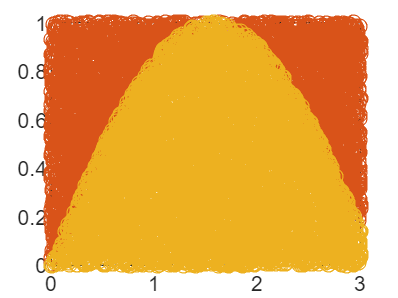

%这个实例展示了如何使用蒙特卡洛算法计算积分的值
total=10000;
underGraph=[0 0];
upGraph=[0 0]; 
for i = 1:total
    x=rand()*3;
    y=rand();
    if y<sin(x)
        underGraph = [underGraph;x,y];
    else
        upGraph = [upGraph;x,y];
    end
end
x=0:0.01:3;
y=sin(x);
plot(x,y);
hold on;
scatter(upGraph(1:size(upGraph),1),upGraph(1:size(upGraph),2));
hold on;
scatter(underGraph(1:size(underGraph),1),underGraph(1:size(underGraph),2));

S = size(underGraph)/(size(upGraph)+size(underGraph));
S = S*3*1

S = 1.9943

%Perfect